# Lab13: Solar image processing to determine the angular velocity of EUV coronal wave

Team1: Dmitry Shadrin, Eugenii Israelit @Skoltech

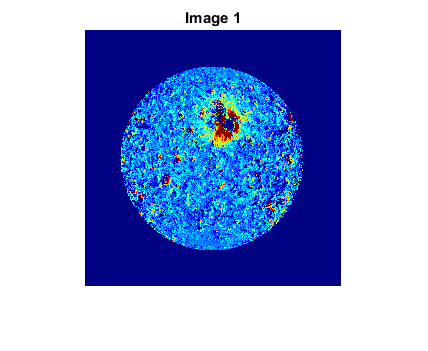

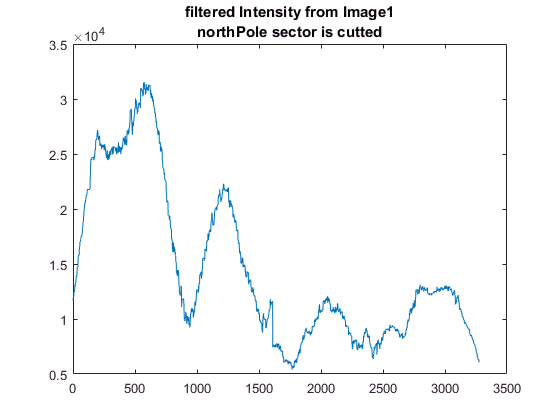

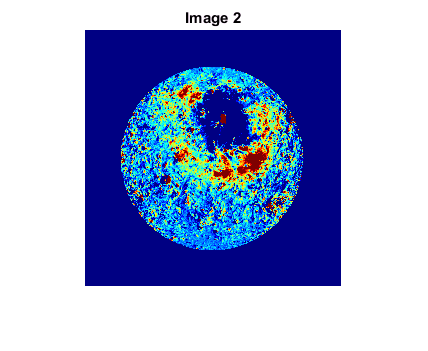

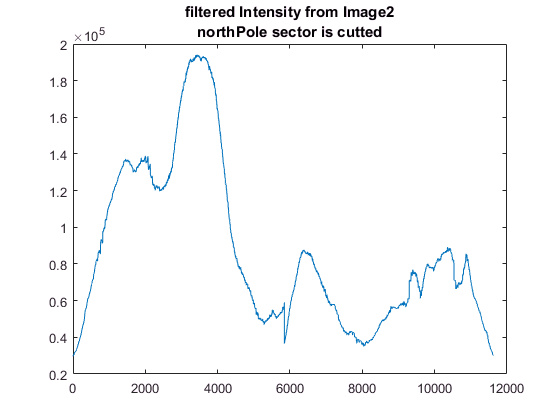

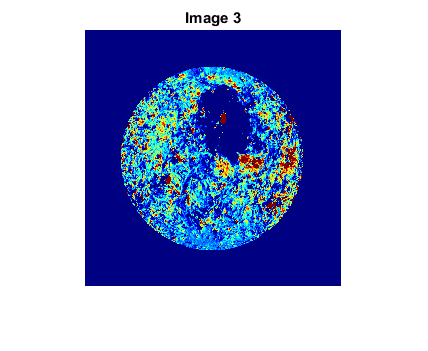

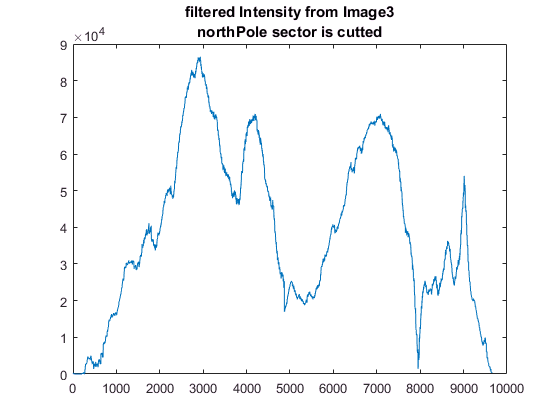

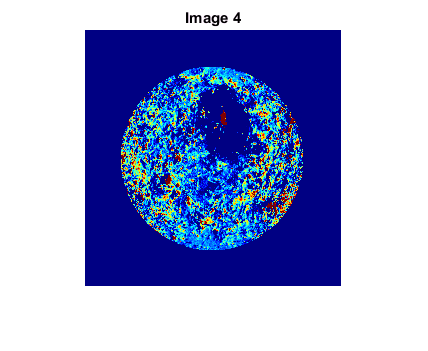

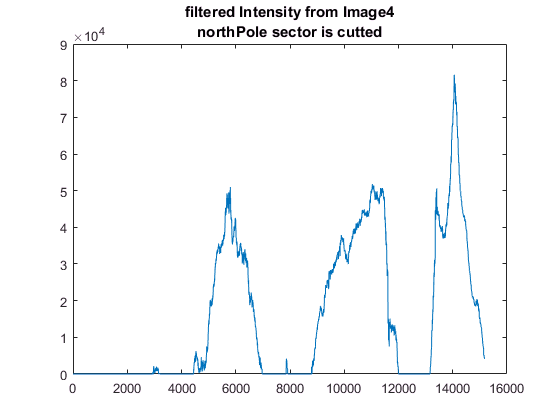

clc; clear; close all;
addpath('functions/', 'Week 7/Lab13/data');
D = importdata('ro.mat');
B = importdata('phi.mat');
Im1 = importdata('Image1.mat');
Im2 = importdata('Image2.mat');
Im3 = importdata('Image3.mat');
Im4 = importdata('Image4.mat');
B1 = importdata('borders1.mat');
B2 = importdata('borders2.mat');
B3 = importdata('borders3.mat');
B4 = importdata('borders4.mat');
Image = {Im1,Im2,Im3,Im4};
Borders = {B1,B2,B3,B4};
Center = zeros(1,4);
Angles = zeros(1,4);

for j=1:4
    Img = Image{j};
    Border = Borders{j};  
    WaveFrontIndex = find( D > Border(1) & D < Border(2) );
    WaveIntensity = Img(WaveFrontIndex);
    WaveAngle = B(WaveFrontIndex);
    [tmp, indexSortedByAngle] = sort(WaveAngle);
    WaveIntensity = WaveIntensity(indexSortedByAngle);
    WaveAngle = WaveAngle(indexSortedByAngle);
    
    %Filtration    
    n = length(WaveAngle);
    FilteredIntensity = zeros(1,n);
    for i=1:n
        FilterIndex=find(WaveAngle > WaveAngle(i)-pi/16 & WaveAngle < WaveAngle(i)+pi/16);     
        FilteredIntensity(i) = sum(WaveIntensity(FilterIndex));
    end
    
    %Cut the north pole sector
    cutInd = find(WaveAngle <= 2 | WaveAngle >= 4);
    Bcut = WaveAngle(cutInd);
    Dcut = FilteredIntensity(cutInd);     
    Dcut(Dcut < 0 ) = 0;  
    k = length(Dcut);
    Center(j) = round ( (sum((1:k).*Dcut))/ sum(Dcut) );
    Angles(j) = Bcut(Center(j)).*(180/pi);

    figure;
        imshow(Img,[-100 300]);
        colormap jet;
        title(['Image ', num2str(j)]);
    figure;
        plot(Dcut);
        title(['filtered Intensity from Image', num2str(j); '  northPole sector is cutted  ' ]);        
end

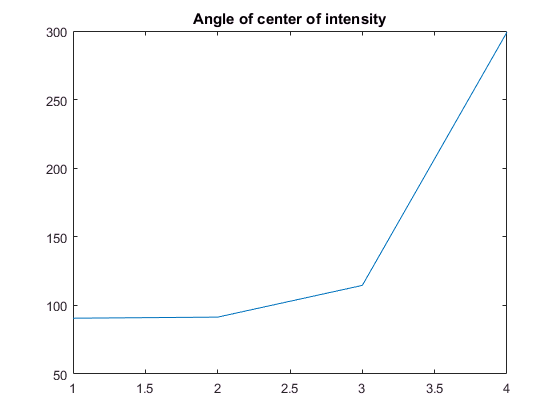

figure;
    plot(Angles);
    title('Angle of center of intensity');